clear

% Load parameters
load_parameters;

% Define the simulation time step
dt = 0.05;

% Start recording how much time the simulation takes
tic

% Pre-allocate arrays to store simulation results
time = 50.0;
z_ref = params.z_eq + 0.02; % Reference position for control
dz_ref = 0; % Reference velocity for control
num_steps = time / dt;
t_result = zeros(num_steps, 1); % Time vector to store simulation time
x_result = zeros(num_steps, 2); % Matrix to store magnet position and velocity

# First assignment

u = 0;

% TODO: tenere in inglese oppure togliere commento
% Dopo vari tentativi eseguiti tramite un for loop per identificare il valore massimo
% entro il quale il sistema non divergeva, il valore di spostamento massimo dall'equilibrio 
% individuato è pari a 1.41m, a 1.42 m il sistema diverge.
% Il ciclo for sottostante plotta l'ultimo valore per il quale il sistema è
% in equilibrio e il primo valore per cui il sistema diverge.
for c = 1.41:0.01:1.42
    z0 = params.z_eq + c;

    % Control loop
    t_current = 0.0;
    x_current = [z0; 0]; % Initial state vector [position; velocity]
    for i = 1:num_steps
        % Store current time and state
        t_result(i) = t_current;
        x_result(i, :) = x_current;
        
        % Update state using ODE integration
        [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
        
        % Update current time and state for next iteration
        t_current = t_out(end);
        x_current = x_out(end, :);
    
    end % for i = 1:num_steps

### Plotting results

We plot the position of the center of the magnet to see the results of the simulation.

Simulation time: 0.71s


z0: 1.46m


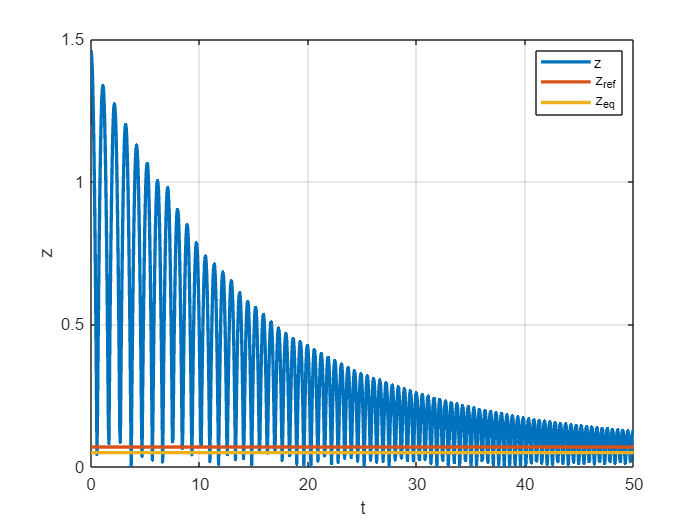

Simulation time: 1.48s


z0: 1.47m


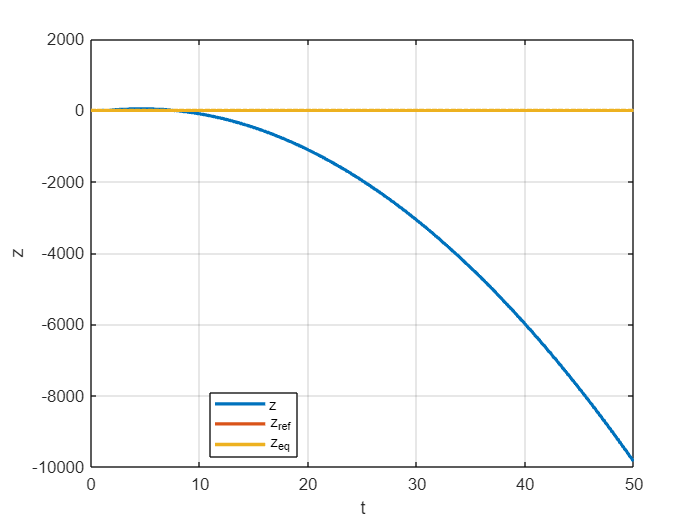

    fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation time
    
    figure;
    clf; grid on; hold on; box on;
    
    fprintf('z0: %.2fm\n', z0) 
    plot(t_result, x_result(:, 1),'linewidth',2)
    plot(t_result, z_ref * ones(num_steps,1),'linewidth',2)
    plot(t_result, params.z_eq * ones(num_steps,1),'linewidth',2)
    legend({'z','z_{ref}','z_{eq}'},'location','best')
    xlabel('t')
    ylabel('z')
end % for c = 1.41:0.01:1.42

clear

# Second assignment

% Load parameters
load_parameters;

% Define the simulation time step
dt = 0.1;

% Start recording how much time the simulation takes
tic

% Initialize variables for control loop
z0 = params.z_eq % Initial condition for magnet position

z0 = 0.0500


% TODO: scrivere cosa si inizializza
numerator = params.b_s/params.z_eq

numerator = 20

denominator = [params.m params.d params.b_m/(params.z_eq)^2]

denominator =     0.0770    0.0001   15.1074


sys_open = tf(numerator,denominator) % requires the Control System Toolbox add-on

sys_open =
 
               20
  ----------------------------
  0.077 s^2 + 0.0001 s + 15.11
 
Continuous-time transfer function.
Model Properties


## Root Locus

We plot the root locus of the open loop.

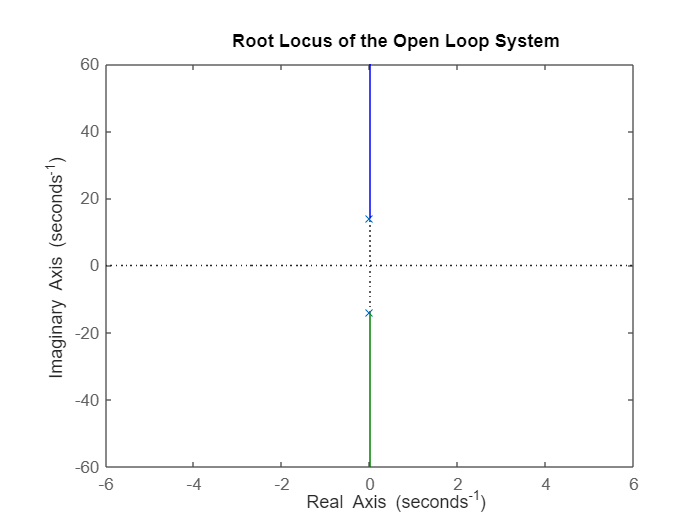

figure;
rlocus(sys_open);
title('Root Locus of the Open Loop System');

## Settling Time

% campione di valori di K da testare
K_values = [1, 5, 10, 50, 100, 200, 500, 1000, 2000, 5000, 10000];

% Prealloco il tempo di assestamento per ogni K
settling_times = zeros(size(K_values));

% Loop attraverso i valori di K per calcolare il tempo di assestamento di
% ognuno
for i = 1:length(K_values)
    K = K_values(i);
    
    sys_closed = feedback(K * sys_open, 1);

    step_info = stepinfo(sys_closed);
    settling_times(i) = step_info.SettlingTime;
end % for i = 1:length(K_values)

We plot the Settling Time for every K value we selected.

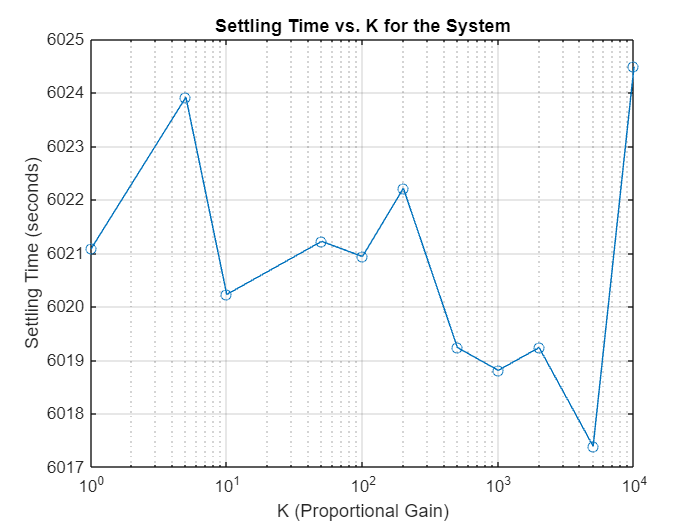

figure;

semilogx(K_values, settling_times, '-o');
xlabel('K (Proportional Gain)');
ylabel('Settling Time (seconds)');
title('Settling Time vs. K for the System');
grid on;

We find the minimum settling time and the corresponding K value.

[min_settling_time, min_index] = min(settling_times);
optimal_K = K_values(min_index);

disp(['Minimum Settling Time: ', num2str(min_settling_time), ' seconds at K = ', num2str(optimal_K)]);

Minimum Settling Time: 6017.3884 seconds at K = 5000


## Simulation

% Pre-allocate arrays to store simulation results
time = 1000.0;
tSpan = linspace(0, time, time/dt); % Time vector with sampling rate of 100Hz
z_ref = params.z_eq + 0.02; % Reference position for control
num_steps = time/dt;
t_result = zeros(num_steps, 1); % Time vector to store simulation time
x_result = zeros(num_steps, 2); % Matrix to store magnet position and velocity
u_signal = zeros(num_steps, 1); % Control signal vector

% Control loop
t_current = 0.0;
x_current = [z0; 0]; % Initial state vector [position; velocity]
for j = 1:length(K_values)
    for i = 1:num_steps
        % Calculate error
        error = z_ref - x_current(1);
        
        % Calculate control signal
        u = K_values(j)*error;
    
        % Store current time and state
        t_result(i) = t_current;
        x_result(i, :) = x_current;
        
        % Update state using ODE integration
        [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
        
        % Update current time and state for next iteration
        t_current = t_out(end);
        x_current = x_out(end, :);
    
    end % for i = 1:num_steps
    
    fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation time

### Plotting results

We plot the position of the center of the magnet to see the results of the simulation.

Simulation time: 3.72s


K_value:1


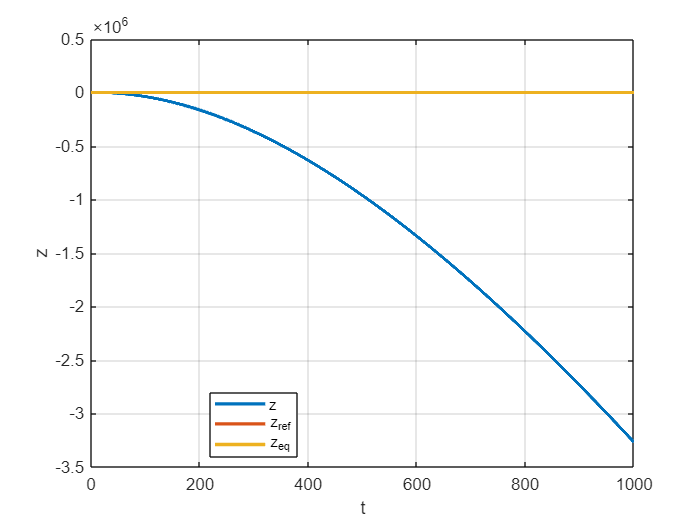

Simulation time: 6.69s


K_value:5


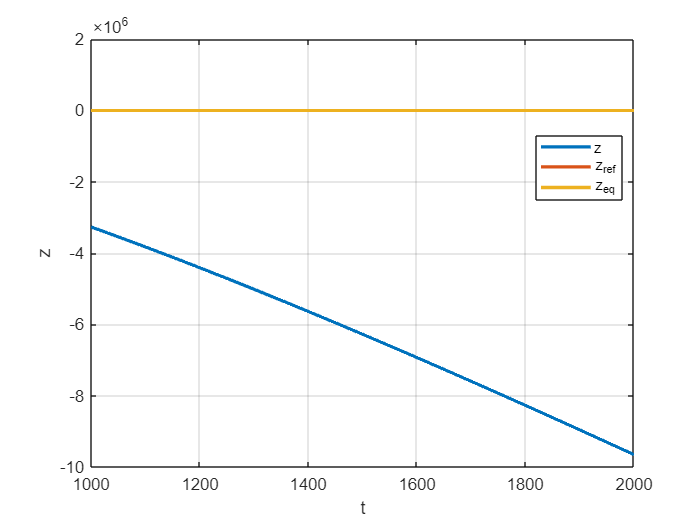

Simulation time: 9.06s


K_value:10


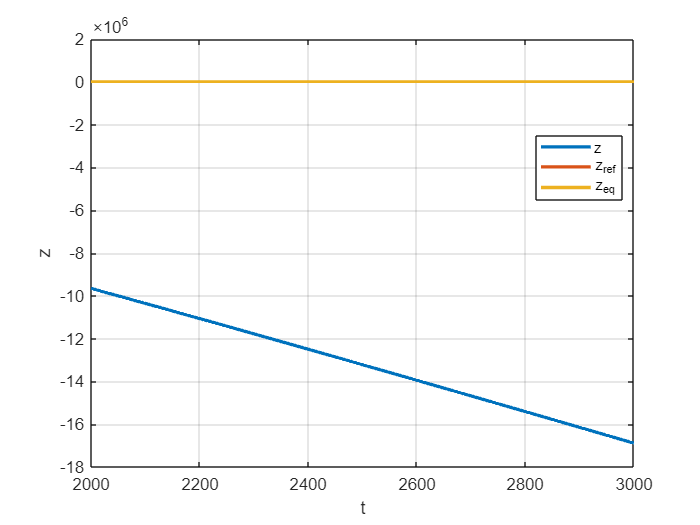

Simulation time: 11.51s


K_value:50


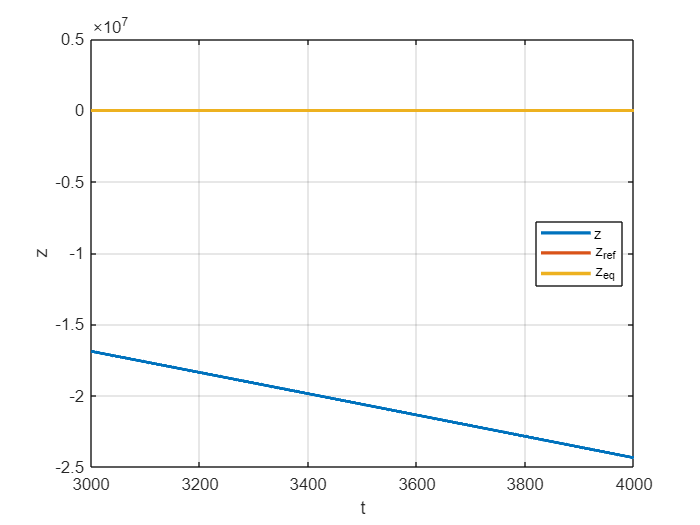

Simulation time: 13.93s


K_value:100


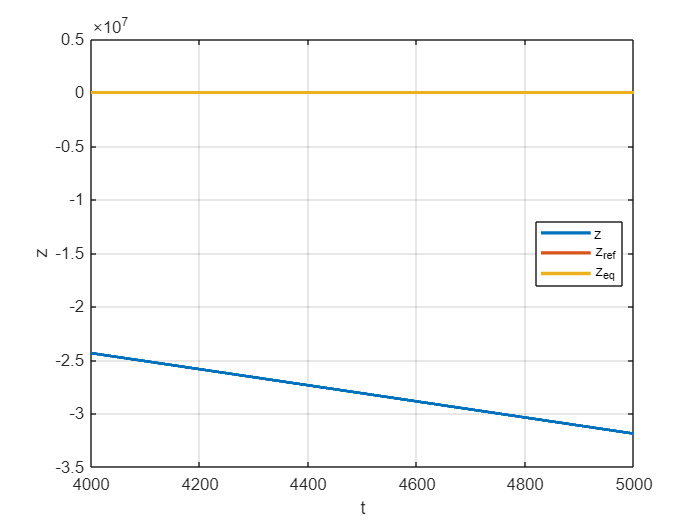

Simulation time: 16.58s


K_value:200


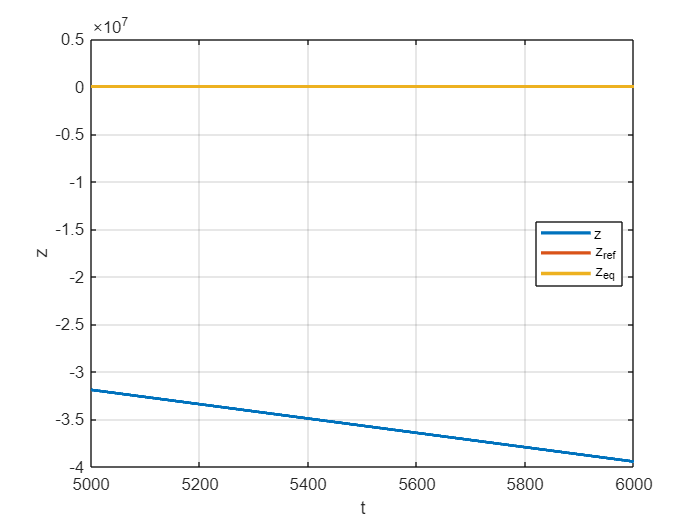

Simulation time: 19.12s


K_value:500


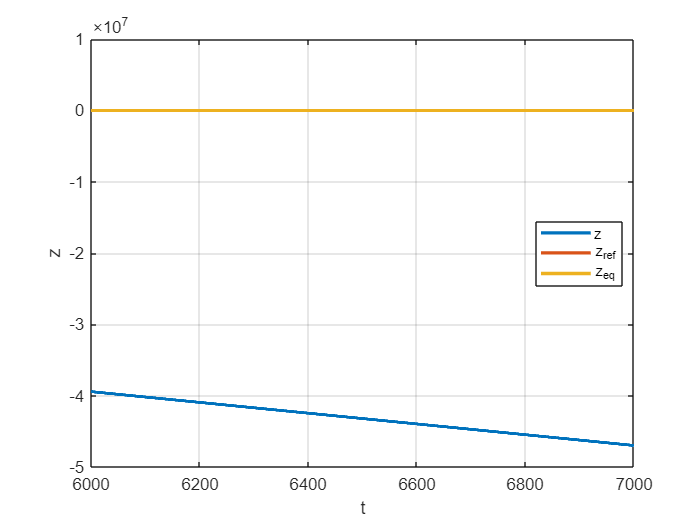

Simulation time: 21.48s


K_value:1000


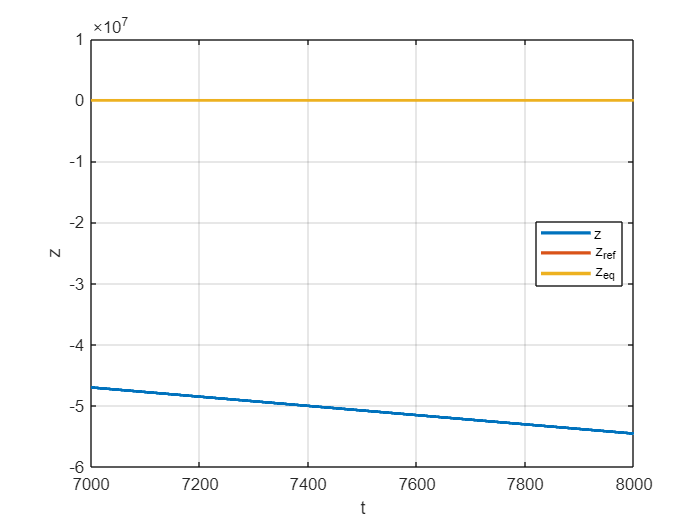

Simulation time: 23.62s


K_value:2000


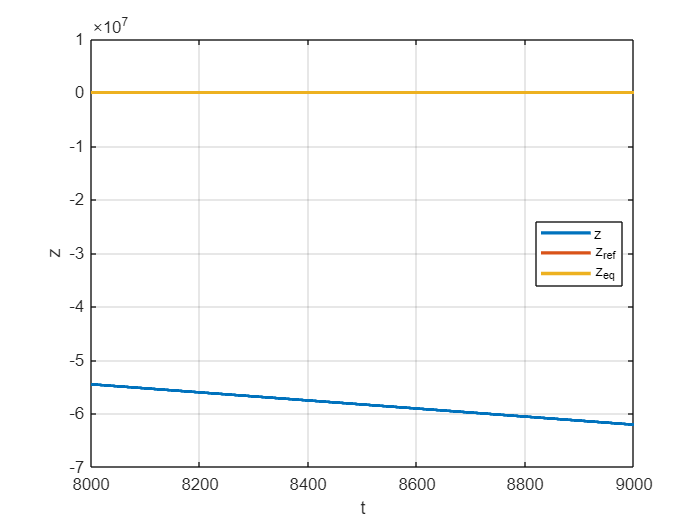

Simulation time: 25.99s


K_value:5000


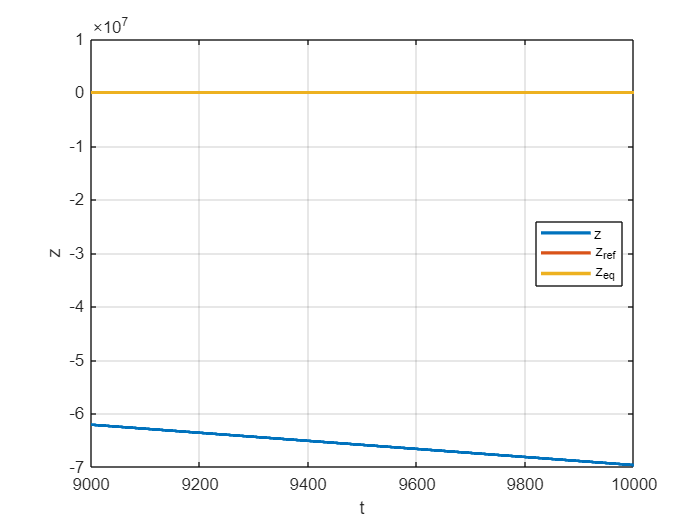

Simulation time: 28.16s


K_value:10000


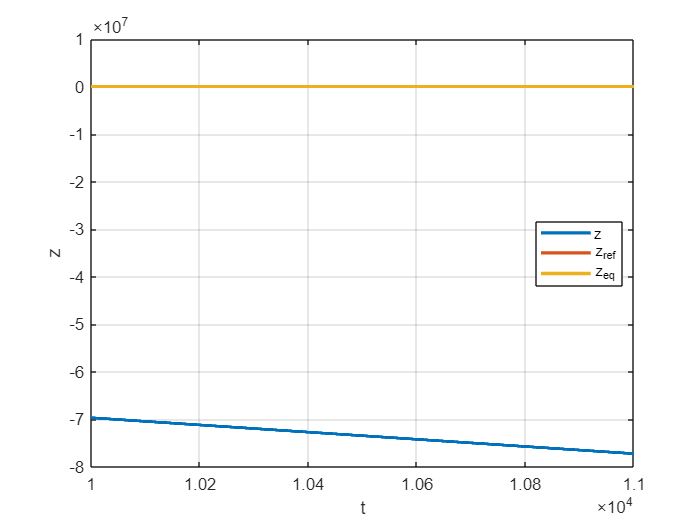

    disp(['K_value:', num2str(K_values(j))]);

    figure;
    clf; grid on; hold on; box on;
    
    plot(t_result, x_result(:, 1),'linewidth',2)
    plot(t_result, z_ref * ones(num_steps,1),'linewidth',2)
    plot(t_result, params.z_eq * ones(num_steps,1),'linewidth',2)
    legend({'z','z_{ref}','z_{eq}'},'location','best')
    xlabel('t')
    ylabel('z')
end % for j = 1:length(K_values)

clear

# Third assignement

clear

# Fourth assignment

clear

# Fifth assignment